**INF6223**

**Devoir 1 - Partie I **

**Par : Pires LUFUNGULA & **

addpath('Résolution\fonctions')  % Ajout du chemin vers les fonctions au chemin de recherche MATLAB

**% Initialisation des chemins vers les fichiers audio**


fichierAudio1 = './Données_Audio/Données/gazouiller.wav'

fichierAudio1 = './Données_Audio/Données/gazouiller.wav'

fichierAudio2 = './Données_Audio/Données/sonor.wav'

fichierAudio2 = './Données_Audio/Données/sonor.wav'

**Lire et écouter les fichiers .wav**

% lecture & audition du fichier fichierAudio1 "gazouiller.wav"
audioinfo(fichierAudio1) %% Affichage des informations

ans = struct with fields:
             Filename: 'D:\Cours\Uqo\Automne 2023\2023-3-INF6223-01 Systèmes de communications multimédias\DEVOIR 1\tp1_MatLab_2023-3-INF6223-01\Données_Audio\Données\gazouiller.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 8000
         TotalSamples: 13129
             Duration: 1.6411
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 8


 
[y,Fs] = audioread(fichierAudio1);  

% Audition du fichier
sound(y,Fs);  

% lecture & audition du fichier fichierAudio2 "sonor.wav"
audioinfo(fichierAudio2) %% Affichage des informations

ans = struct with fields:
             Filename: 'D:\Cours\Uqo\Automne 2023\2023-3-INF6223-01 Systèmes de communications multimédias\DEVOIR 1\tp1_MatLab_2023-3-INF6223-01\Données_Audio\Données\sonor.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 8192
         TotalSamples: 73113
             Duration: 8.9249
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 8



[y2,Fs2] = audioread(fichierAudio2); % la fréquence d'échantillonnage dans la variable Fs2.
sound(y2,Fs2);  % Audition du fichier


**R1/ La fréquence d’échantillonnage Fe**

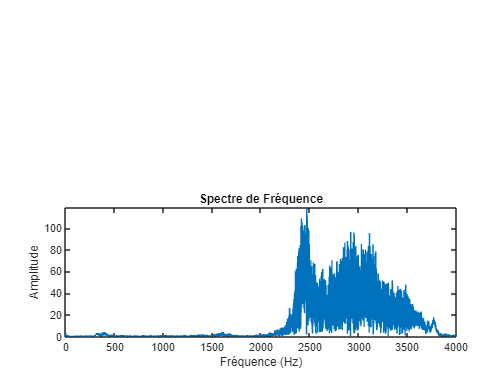

La fréquence d'échantillonnage (Fe) est : 8000 Hz


%Fe fichierAudio1 (gazouiller.wav)
figure;
afficher_info_audio(y,Fs)

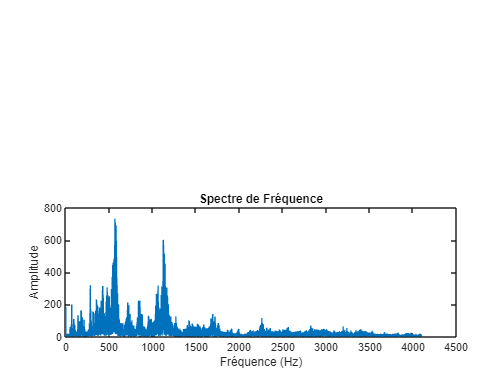

La fréquence d'échantillonnage (Fe) est : 8192 Hz



%Fe fichierAudio2 (sonor.wav)
figure;
afficher_info_audio(y2,Fs2)

**R2/  Le nombre de bits/sec du train de bits (bitstream) correspondant**

%Nbr de bits/sec pour fichierAudio1(gazouiller.wav)

debitBinaireAudio1 = calculer_debit_binaire(Fs)

debitBinaireAudio1 = 64000

disp(['Le débit binaire de fichierAudio1 (avec la résolution par 8 bit) est de ', num2str(debitBinaireAudio1), ' bits/sec.']); 

Le débit binaire de fichierAudio1 (avec la résolution par 8 bit) est de 64000 bits/sec.



%Nbr de bits/sec pour le fichierAudio2(sonor.wav)

debitBinaireAudio2 = calculer_debit_binaire(Fs2)

debitBinaireAudio2 = 65536

disp(['Le débit binaire de fichierAudio2 (avec la résolution par 8 bit) est de ', num2str(debitBinaireAudio2), ' bits/sec.']); 

Le débit binaire de fichierAudio1 (avec la résolution par 8 bit) est de 65536 bits/sec.


**R3/  L’amplitude minimale et maximale des échantillons audio**


fprintf('L’amplitude minimale et maximale des échantillons audio de deux fichiers\n');

L’amplitude minimale et maximale des échantillons audio de deux fichiers


calculer_amplitude_min_max(8)

L'amplitude minimale des échantillons audio pour une résolution de 8 bits est : -128
L'amplitude maximale des échantillons audio pour une résolution de 8 bits est : 127


**R4/  L’amplitude du 1000ième échantillon**

% Calcul de l'amplitude du 1000ième échantillon fichierAudio1(gazouiller.wav)
amplitude_1000eme_echantillon_audio1 = y(1000) - 128; 

% Afficher l'amplitude du 1000ième échantillon
disp('Amplitude du 1000ième échantillon audio1:');

Amplitude du 1000ième échantillon audio1:


disp(amplitude_1000eme_echantillon_audio1);

 -128.0391




% Calcul de l'amplitude du 1000ième échantillon fichierAudio2(sonor.wav)
amplitude_1000eme_echantillon_audio2 = y2(1000) - 128; 

% Afficher l'amplitude du 1000ième échantillon
disp('Amplitude du 1000ième échantillon audio2:');

Amplitude du 1000ième échantillon audio2:


disp(amplitude_1000eme_echantillon_audio2);

 -127.9375



**R5/  Représenter graphiquement, avec stem ( ) puis avec plot ( ), une portion de 100 échantillons de l’un des 2 signaux**** "fichierAudio1(gazouiller.wav)".**

% fichierAudio1(gazouiller.wav)
portion = y(1:100);

- Représentation avec stem()

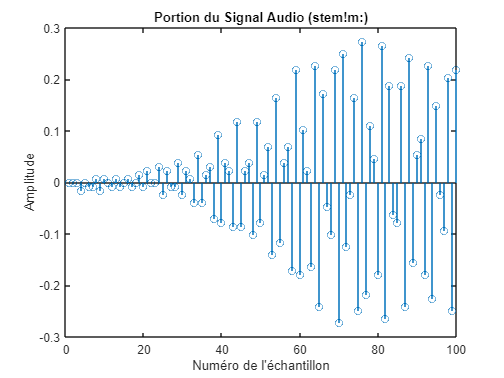

figure;
stem(1:100, portion);
title('Portion du Signal Audio (stem!m:)');
xlabel('Numéro de l''échantillon');
ylabel('Amplitude');

- Représentation avec plot()

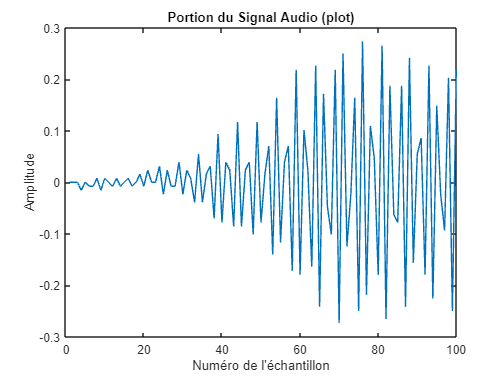

figure;
plot(1:100, portion);
title('Portion du Signal Audio (plot)');
xlabel('Numéro de l''échantillon');
ylabel('Amplitude');

Le choix des 100 premiers échantillons permet de fournir une portion représentative du début du signal audio. Cela donne une première impression de l’attrait général et des caractéristiques du signal au début. Ces 100 échantillons fournissent suffisamment de données pour visualiser sans surcharger le graphique. De plus, cette première partie du signal peut souvent fournir des informations extrêmement utiles sur les propriétés du signal audio, telles que le niveau moyen du signal, les transitions ou d'autres caractéristiques importantes.

La représentation visuelle de cette partie du signal audio est fournie par les figures **stem() et plot()**, qui montrent l'amplitude en fonction du numéro d'échantillon. Le premier utilise un graphique en **tiges** pour afficher chaque échantillon individuellement, tandis que le second utilise un graphique linéaire pour afficher **l'évolution de l'amplitude sur les échantillons**. Ces représentations permettent d'observer le comportement du signal audio dans cette partie initiale.

**R6/  Représenter graphiquement, avec stem ( ) puis avec plot ( ), une portion de 100 échantillons de l’un des 2 signaux**** "fichierAudio1(gazouiller.wav)".**

% fichierAudio1(gazouiller.wav)
portion = y(1:100);